# Stream PSD using a Loop

Load data and create source object

load ./data/monitoredfan.mat
src = dsp.SignalSource(monitoredfan,100000);

Create analyzer object

analyzer = spectrumAnalyzer("SampleRate",fs,"PlotAsTwoSidedSpectrum",false);

Power spectrum in loop

while ~isDone(src)
    frame = src(); 
    analyzer(frame);
    pause(1)
    drawnow
end

Release objects

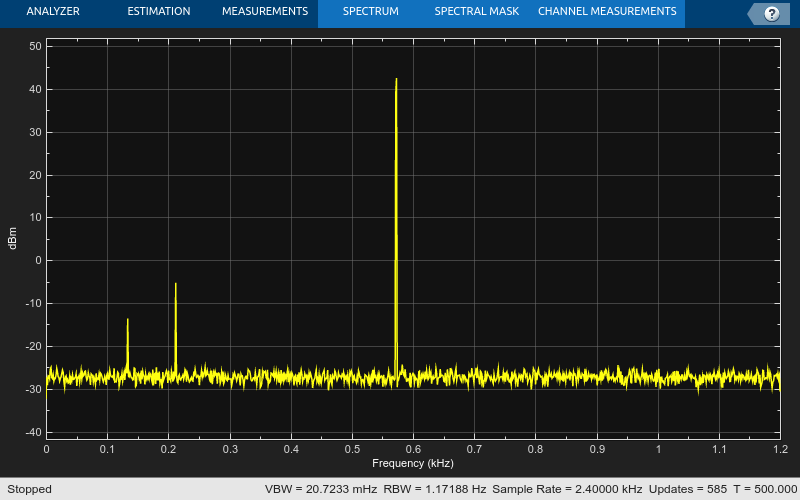

release(analyzer);

release(src);